%% Initialization

clear;
bins = 300;

files.name = 'DCMot_ModelOutput';

%% 1. Step: Extract min/max values for each column that will be used
p_min  = 0; p_max = 0;
ac_min = 0; ac_max = 0;
v_min  = 0; v_max = 0;
a_min  = 0; a_max = 1.0;
s_min  = 0; s_max = 0;

domain_string = '';


%for file_index = 1:length(files)
load(files.name,'SimData');

position      = SimData(:,2);
velocity      = SimData(:,3);
accelaration  = SimData(:,4);
action        = SimData(:,10);
muscle_sensor = SimData(:,5);


files.position       = position;
files.velocity       = velocity;
files.accelaration   = accelaration;
files.action         = action;
files.msensor        = muscle_sensor;


p_min = min(position);
p_max = max(position);

v_min = min(velocity);
v_max = max(velocity);

s_min = min(muscle_sensor);
s_max = max(muscle_sensor);

ac_min = min(accelaration);
ac_max = max(accelaration);

a_min = min(action);
a_max = max(action);

%end

domain_string = [domain_string 'Domains\n' ...
    sprintf('  Position:        %f, %f\n', p_min, p_max) ...
    sprintf('  Velocity:        %f, %f\n', v_min, v_max) ...
    sprintf('  Accelaration:    %f, %f\n', ac_min, ac_max) ...
    sprintf('  Muscle sensor:   %f, %f\n', s_min, s_max) ...
    sprintf('  Actuator signal: %f, %f\n', a_min, a_max)]

domain_string =     'Domains\n  Position:        0.879274, 1.070177
       Velocity:        -1.462496, 1.185607
       Accelaration:    -10.000000, 30.945830
       Muscle sensor:   0.000000, 27.777651
       Actuator signal: -16.203697, 19.328333
     '



%Discretise Test
fprintf('Bins = %d\n', bins)

Bins = 300


w_bins = bins;
a_bins = bins;
s_bins = bins;
files.d_position     = discretiseMatrix(position, p_min, p_max, w_bins);
files.d_velocity     = discretiseMatrix(velocity, v_min, v_max, w_bins);
files.d_accelaration = discretiseMatrix(accelaration, ac_min, ac_max, w_bins);
files.a              = discretiseMatrix(action, a_min, a_max, a_bins);


% create univariate variable
files.w              = combineAndRelabelBinnedMatrix([files.d_position, files.d_velocity, files.d_accelaration]);
    

%measure MC 

fprintf('Working on file %s\n', files.name)

Working on file DCMot_ModelOutput


w2 = files.w(2:end,:)

w2 =    233
   232
   231
   230
   229
   227
   226
   225
   224
   223


w1 = files.w(1:end-1,:)

w1 =    234
   233
   232
   231
   230
   229
   227
   226
   225
   224


a1 = files.a(1:end-1,:)

a1 = 8001×1 int64 column vector
   137
   137
   137
   137
   137
   137
   137
   137
   137
   137


%s1 = files.s(1:end-1,:);
% for t = 1:length(w1)
%     w2index = w2(t)
%     w1index = w1(t)
%     a1index = a1(t)
% end

files.mcw  = MC_W1(w2, w1, a1);
fprintf('MC_W %f\n', files.mcw);

MC_W 4.963457


mcwd = MC_W1_dynamic(w2, w1, a1);
files.mcd  = mcwd;
fprintf('check %f\n', files.mcw - mean(mcwd));

check 0.000000


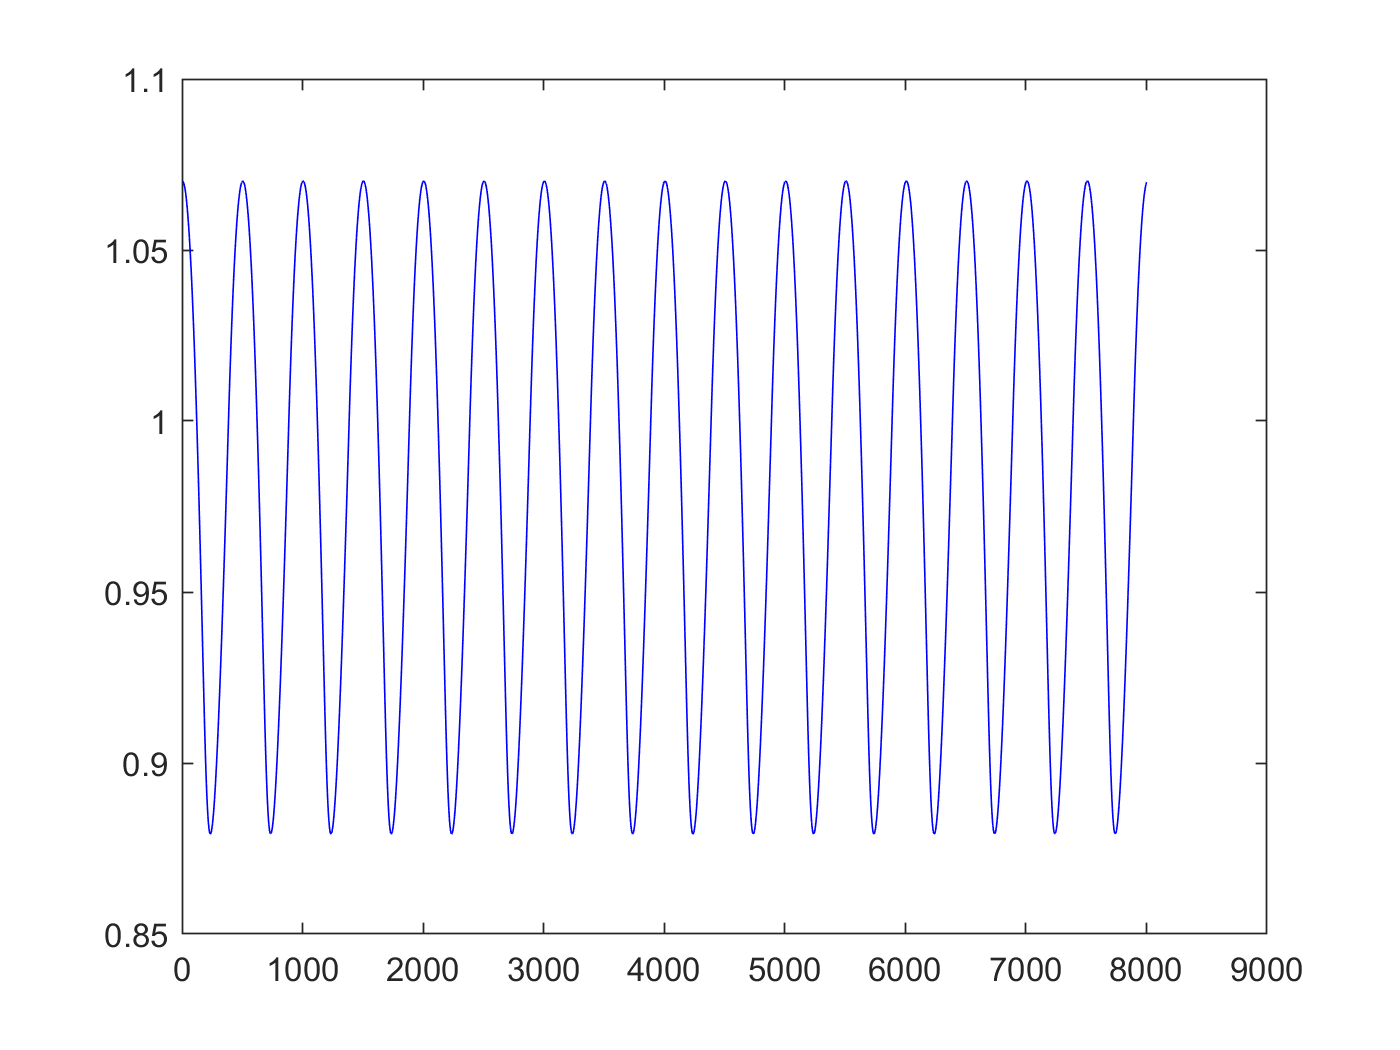

plot(files.position,'b')

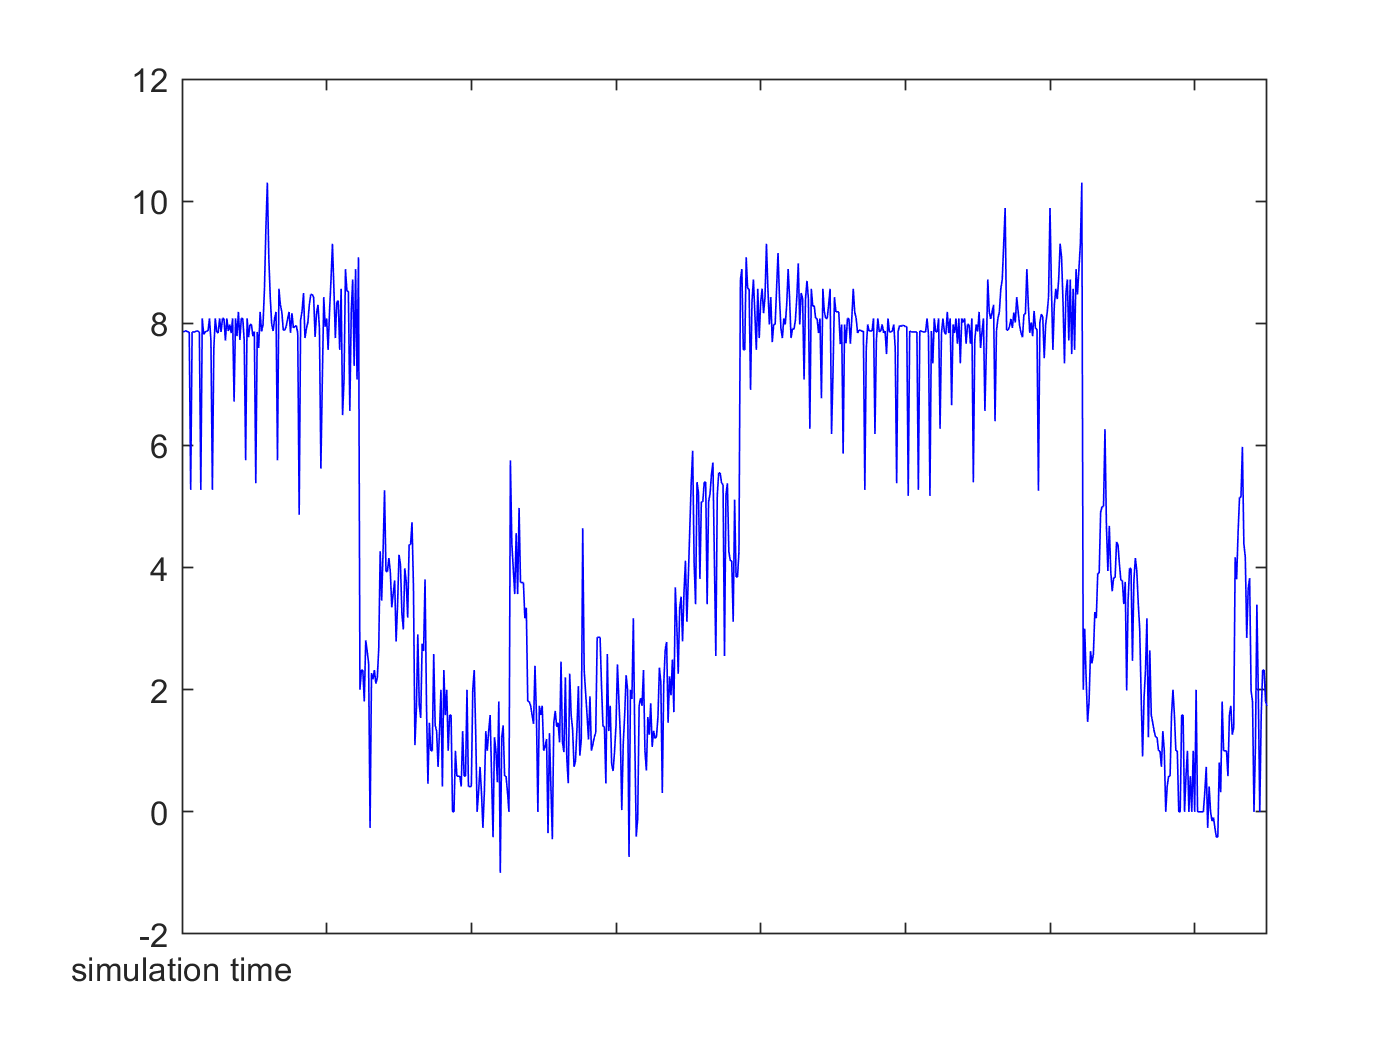


hold off;

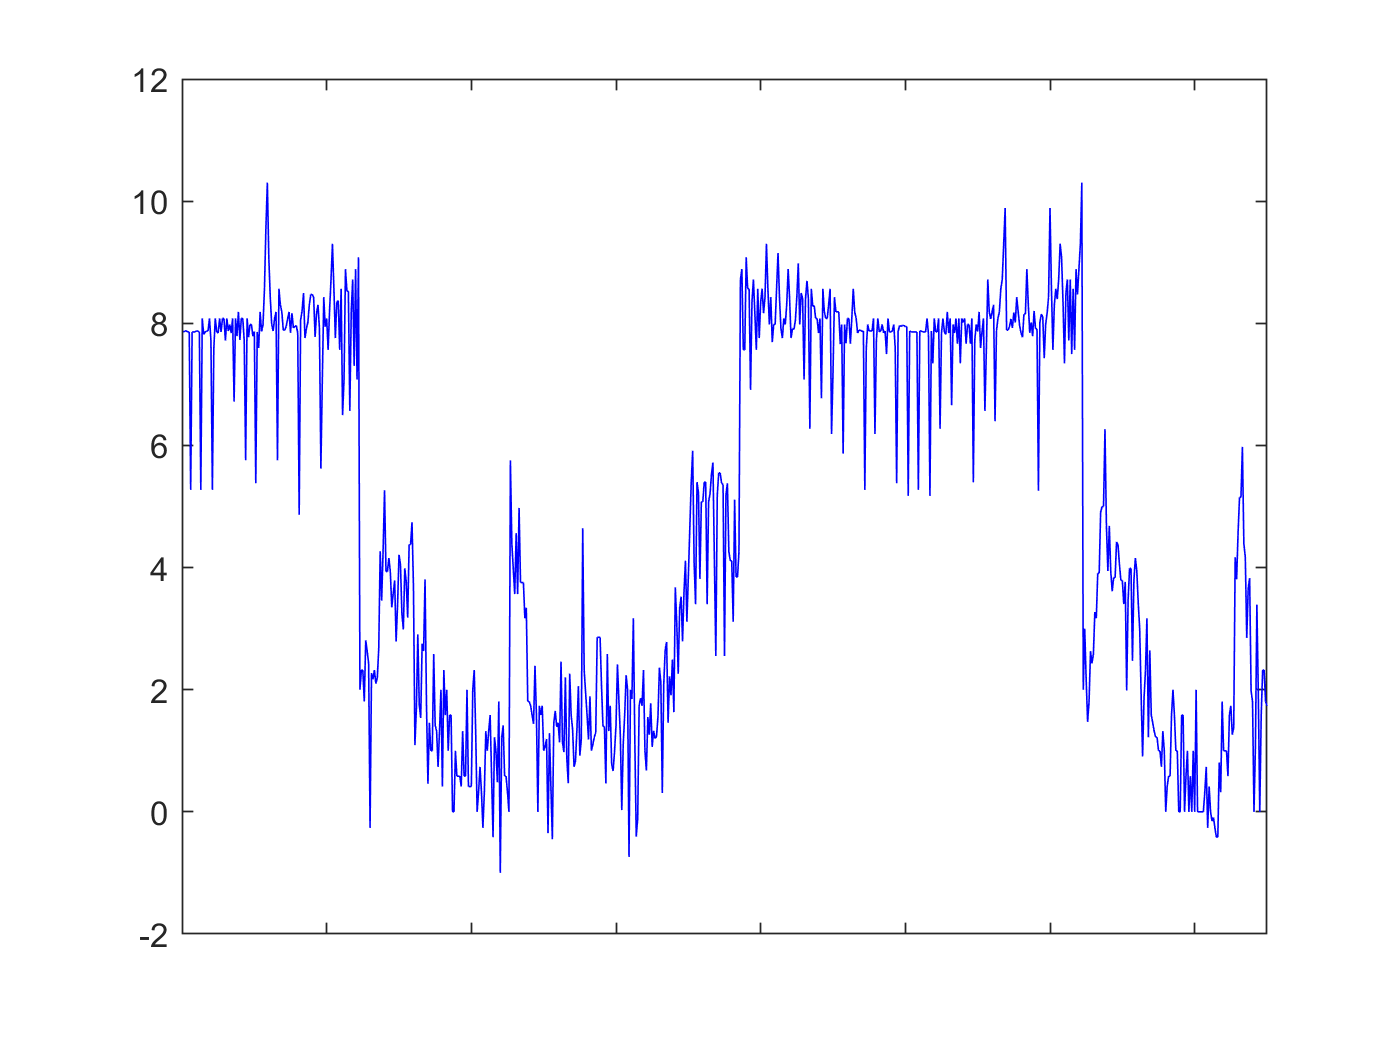

plot(files.mcd,'b')

xlim([0 750])
xticklabels([''])
ylim([-2.0 12.0])

files.smooth_mcd = smoothdata(files.mcd,'gaussian');

Reference to non-existent field 'mcd'.

hold off
plot(files.smooth_mcd)
%xlim([0 300000]);
